# Crystal lattice image and distortion of that image v.2

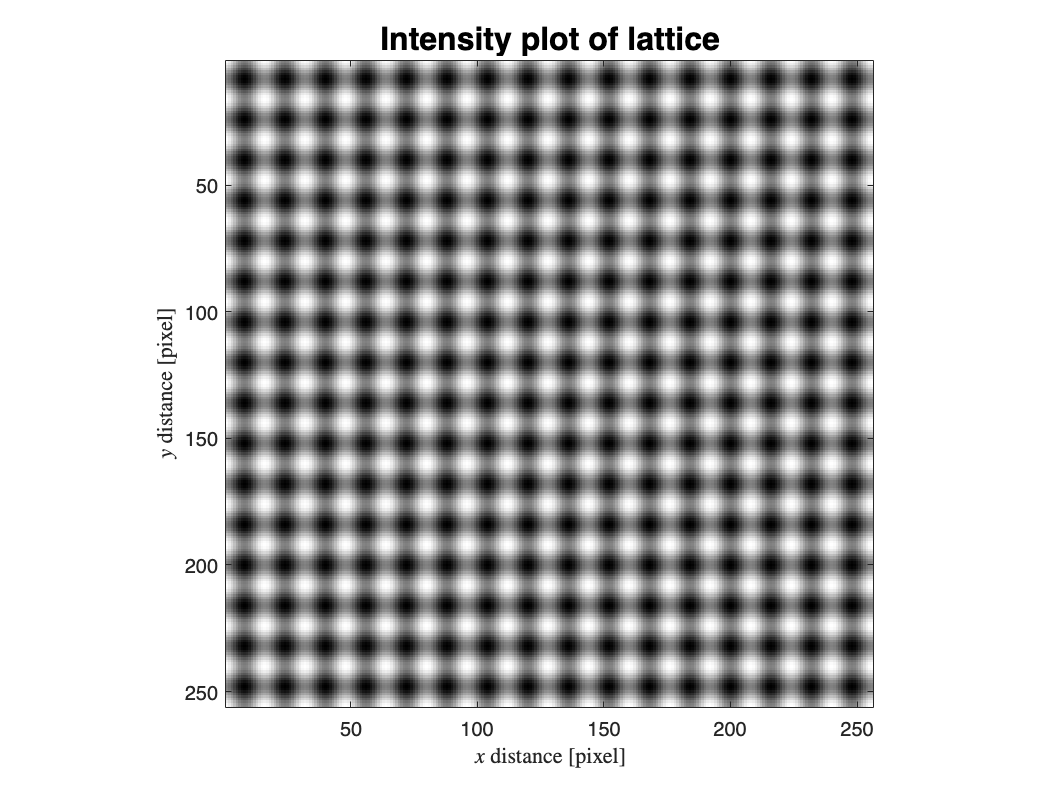

image_length = 256;
image_height = 256;
lattice_constant = 16;

[x,y] = meshgrid(1:image_length,1:image_height);
q_x = 2*pi/lattice_constant;
q_y = 2*pi/lattice_constant;
lattice = cos(q_x*x)+cos(q_y*y);
plotLat(lattice,"lattice")
colormap(gray);


lambda = 0.4;
lambda = lambda/lattice_constant;

% lattice_x = exp(1i.*q_x.*x);
% imagesc(real(lattice_x))
% imagesc(imag(lattice_x))
% 
% lattice_y = exp(1i.*q_y.*y);
% imagesc(real(lattice_y))
% imagesc(imag(lattice_y))

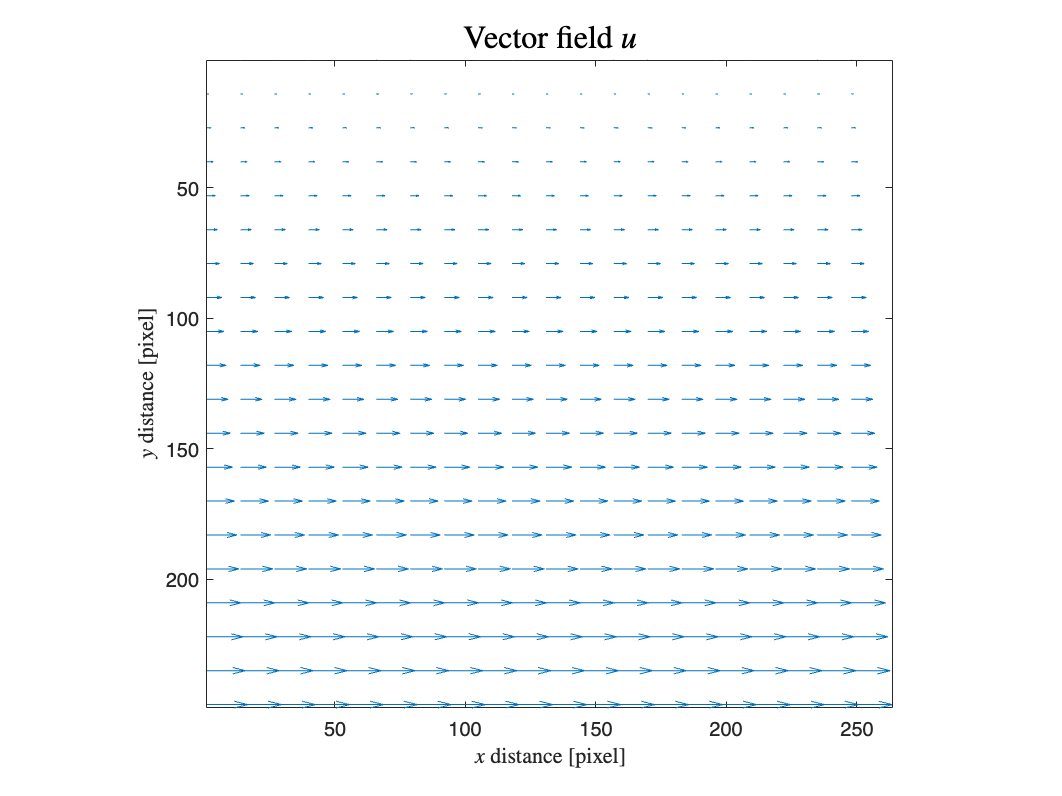

u = uCreate(image_height,image_length,10);

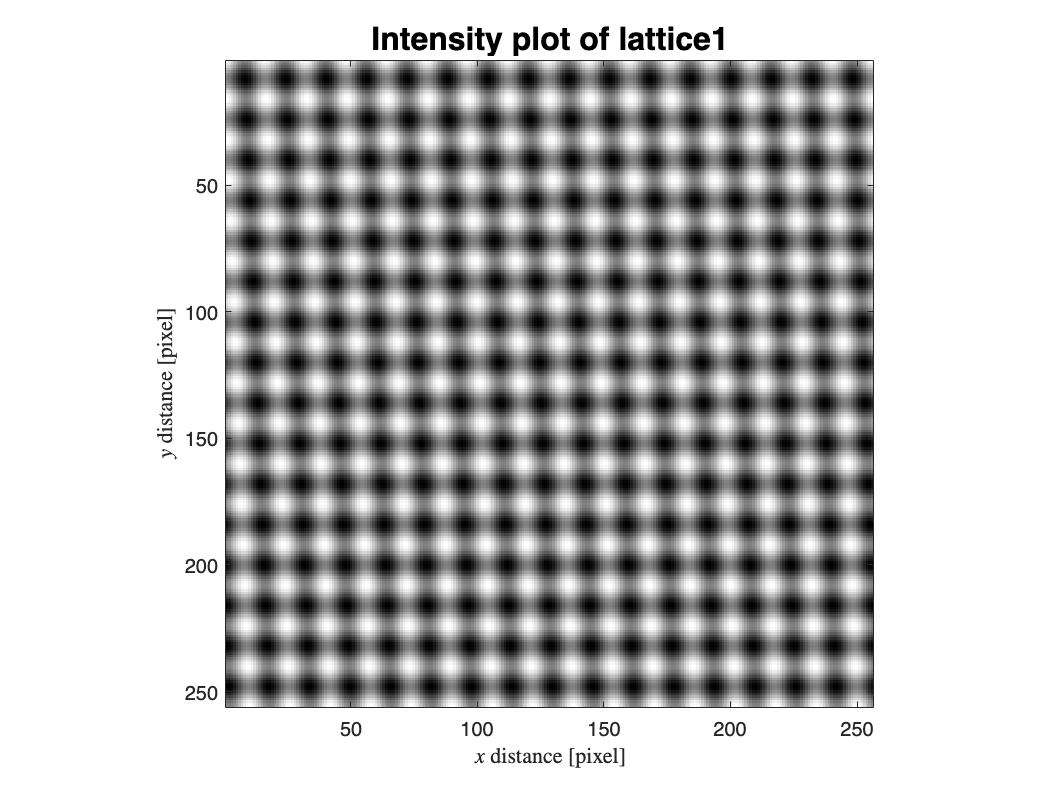


lattice1 = cos(q_x*(x-squeeze(u(:,:,1))))+cos(q_y*(y-squeeze(u(:,:,2))));
plotLat(lattice1,"lattice1")

% lattice1_x = zeros(image_height,image_length);
% 
% lambda = 0.05;
% 
% tic
% for k = 1:image_length
%     for l = 1:image_height
%         expr = (lattice1.*exp(-1i*q_x*x).*exp(-lambda^2*abs((k-x).^2+(l-y).^2))/2)*lambda^2/(2*pi);
%         lattice1_x(l,k) = sum(expr,"all");
%     end
% end
% toc
% 
% imagesc(real(lattice1_x))
% title("T_x (real)");
% colorbar
% axis image
% imagesc(imag(lattice1_x))
% title("T_x (imaginary)");
% colorbar
% axis image
% 
% lattice1_y = zeros(image_height,image_length);
% 
% tic
% for k = 1:image_length
%     for l = 1:image_height
%         expr = (lattice1.*exp(-1i*q_y*y).*exp(-lambda^2*abs((k-x).^2+(l-y).^2))/2)*lambda^2/(2*pi);
%         lattice1_y(l,k) = sum(expr,"all");
%     end
% end
% toc
% 
% imagesc(real(lattice1_y))
% title("T_y (real)");
% colorbar
% axis image
% imagesc(imag(lattice1_y))
% title("T_y (imaginary)");
% colorbar
% axis image

% ucalc_x = -unwrap(angle(lattice1_x*2))./q_x;
% ucalc_y = -unwrap(angle(lattice1_y*2))./q_y;
% 
% u1(:,:,1) = ucalc_x;
% u1(:,:,2) = ucalc_y;
% 
% uPlot(u1,image_height,image_length);

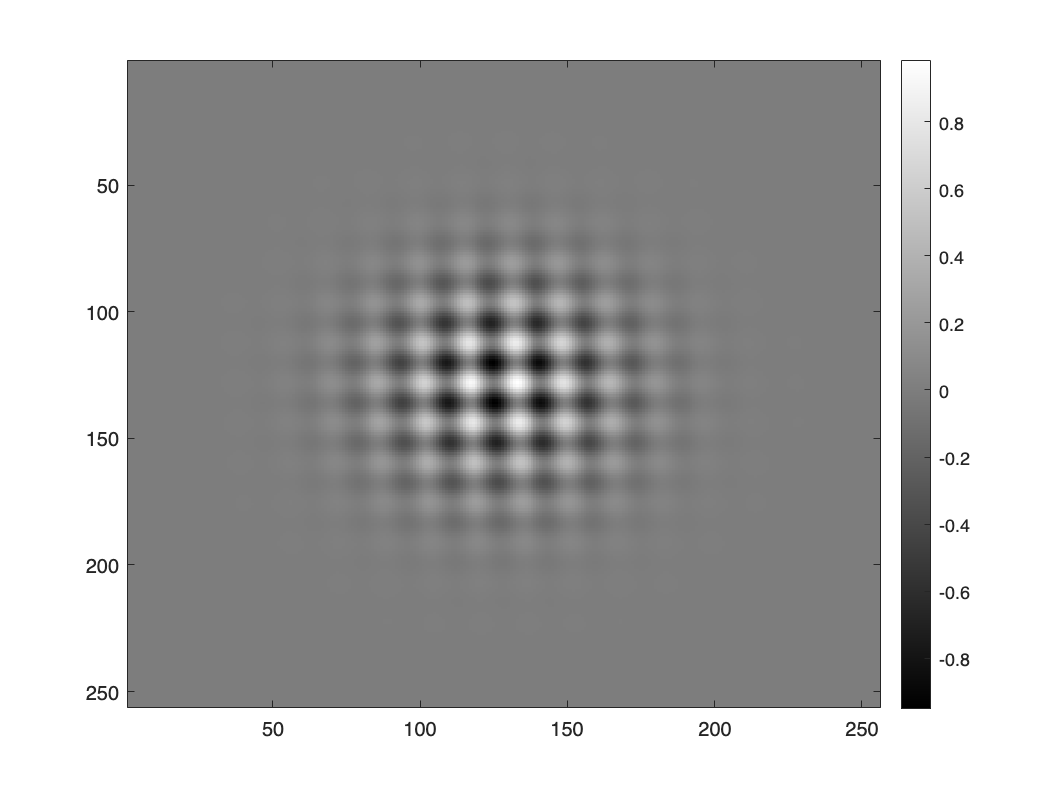

% lambda = 0.05;
% ab = (lattice1.*exp(-1i*q_x*x).*exp(-lambda^2*abs((128-x).^2+(128-y).^2))/2)*lambda^2/(2*pi);
ab = (lattice1.*exp(-lambda^2*abs((128-x).^2+(128-y).^2))/2);
imagesc(real(ab))
colorbar

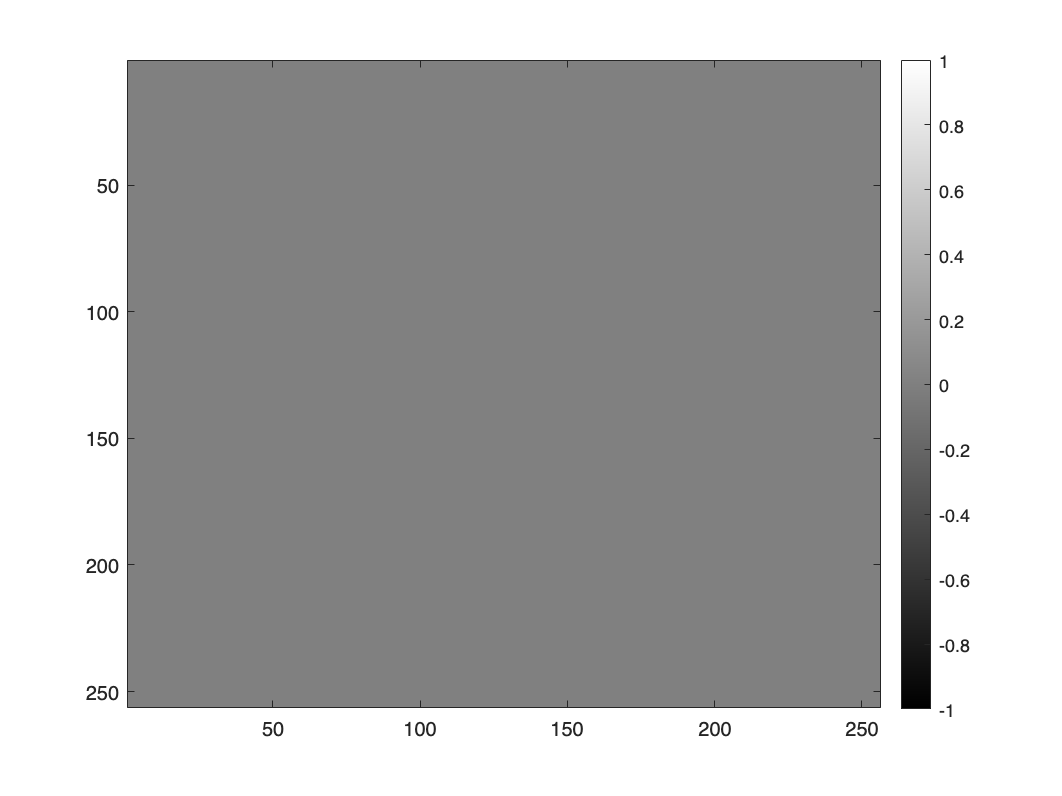

imagesc(imag(ab))
colorbar

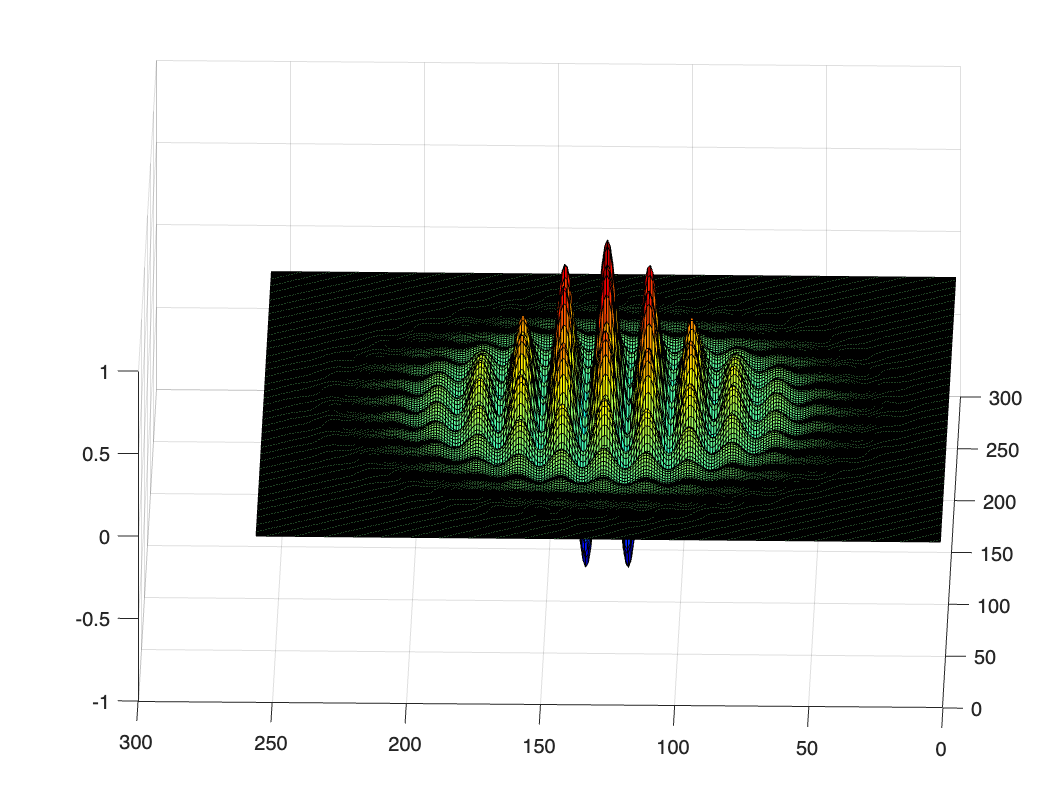


surf(real(ab))
colormap(jet)
view([-88.71355 43.32306])

An attempt to do this by convolution

% lambda = 0.05;
% 
% G = fspecial('gaussian',[image_height image_length],1/lambda).*lambda/sqrt(2*pi);
% 
% % the lambda/2pi factor is there to follow equation S6 from Fujita's Paper
% Fx = lattice1.*exp(-1i*q_x*x);
% tic
% lattice1_x1 = conv2(Fx,G,'same');
% toc
% imagesc(real(lattice1_x1))
% title("T_x (real)");
% colorbar
% axis image
% 
% colormap("gray");
% 
% imagesc(imag(lattice1_x1))
% title("T_x (imaginary)");
% colorbar
% axis image
% tic
% Fy = lattice1.*exp(-1i*q_y*y);
% toc
% lattice1_y1 = conv2(Fy,G,'same');
% 
% imagesc(real(lattice1_y1))
% title("T_y (real)");
% colorbar
% axis image
% imagesc(imag(lattice1_y1))
% title("T_y (imaginary)");
% colorbar
% axis image
% 
% ucalc_x1 = -unwrap(angle(lattice1_x1*2))./q_x;
% ucalc_y1 = -unwrap(angle(lattice1_y1*2))./q_y;
% 
% u2(:,:,1) = ucalc_x1;
% u2(:,:,2) = ucalc_y1;
% 
% uPlot(u2,image_height,image_length);

IT WORKED!!! SASJDFHALSJDHF

## Functions

function plotLat(P0,nm1,r,num)
    % P0 is the image (uint8); nm1 is the title; r, num specify the view
    
    imagesc(P0);
    colormap(gray);
    axis image
    if nargin<4
        num = 8;
        if nargin>2
            xlim([1 r*num]);
            ylim([1 r*num]);
        end
    else
        xlim([1 r*num]);
        ylim([1 r*num]);
    end
    
    xlabel("$x$ distance [pixel]","Interpreter","latex");
    ylabel("$y$ distance [pixel]","Interpreter","latex");
    t = title("Intensity plot of " + nm1);
    t.FontSize = 16;
end



function s = uCreate(h,l, scale_mag)
    % just to avoid clutter
    s = zeros(h,l,2);
    scale_coor = 1; % to scale the coordinates of the vector field
    if nargin<3
        scale_mag = 15; % to scale the magnitude of the vectors in the vector field
    end
    [x,y] = meshgrid(1:l,1:h);
    x = scale_coor.*x./l;
    y = scale_coor.*y./h;
    
    % change these to change the vector field u
    s(:,:,1) = y*scale_mag;
    s(:,:,2) = 0*scale_mag;
    
    uPlot(s,h,l,scale_coor);
end

function uPlot(s,h,l,scale_coor)
    if nargin<4
        scale_coor = 1;
    end
    
    [v,w] = meshgrid(1:l,1:h);
    
    skipx = ceil(50*l/1024);
    skipy = ceil(50*h/1024);
    
    quiver(v(1:skipx:end,1:skipy:end).*scale_coor,w(1:skipx:end,1:skipy:end).*scale_coor, ...
        s(1:skipx:end,1:skipy:end,1),s(1:skipx:end,1:skipy:end,2));
    t = title("Vector field $u$","Interpreter","latex");
    xlabel("$x$ distance [pixel]","Interpreter","latex");
    ylabel("$y$ distance [pixel]","Interpreter","latex");
    set(gca,"YDir","reverse");
    axis equal tight;
    t.FontSize = 16;
end